# Solution to the *Median House Price – Regression *exercise

## 1. Load data

Load the data in `housePrices.mat`.

load housePrices

This file contains a table `housing` with 16 variables related to house prices in about 500 locations. The last variable of housing, `MedianValue`, is the response variable. The MAT-file also contains the tables `houseTrain` and `houseTest`, which represent a disjoint partition of `housing` into a training and testing set.

## 2. Fit a linear model

Fit a linear regression model to the training set, using all 15 predictor variables to predict median house value.

mdl = fitlm(houseTrain);

## 3. Predict and evaluate

Use the linear model to predict the median house value for the observations in the testing set. Compare the predicted values to the actual values. You can use the `evaluatefitHouse` function provided with the course example files to visualize the results.

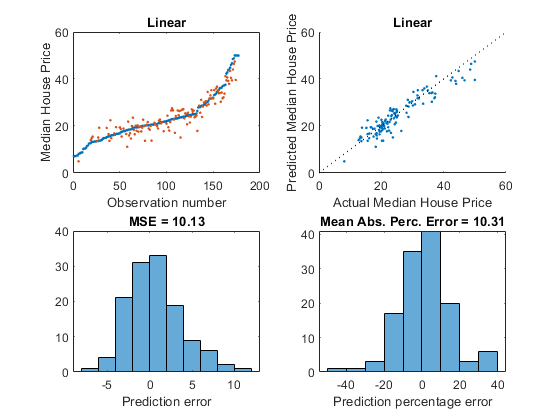

qualpred = predict(mdl,houseTest);
evaluatefitHouse(houseTest.MedianValue,qualpred,'Linear')

## 4. Use stepwise fitting

Repeat steps 2 and 3, using stepwise fitting to fit a reduced linear model.

mdl = stepwiselm(houseTrain,'Upper','linear');

1. Adding LowerStatus, FStat = 388.9494, pValue = 1.352149e-57
2. Adding rooms, FStat = 92.0067, pValue = 2.34803e-19
3. Adding TaxRate, FStat = 4.3652, pValue = 2.2056e-19
4. Adding PupilTeacher, FStat = 59.6735, pValue = 2.96603e-13
5. Adding Distance, FStat = 13.3455, pValue = 0.000317821
6. Adding HouseAge, FStat = 10.7087, pValue = 0.00122319
7. Adding YCoord, FStat = 5.1162, pValue = 0.024603
8. Adding BBT, FStat = 4.9035, pValue = 0.02775
9. Removing LowerStatus, FStat = 2.3986, pValue = 0.12277


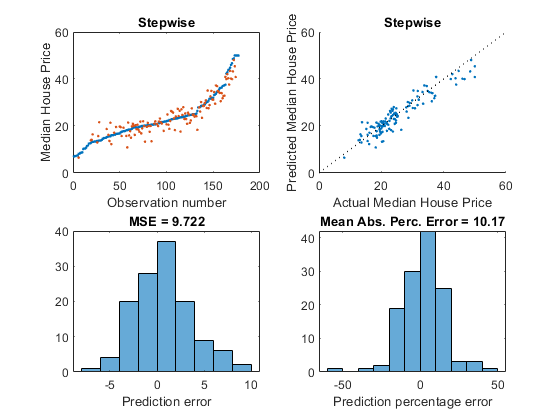

qualpred = predict(mdl,houseTest);
evaluatefitHouse(houseTest.MedianValue,qualpred,'Stepwise')

## 5. Try a nonparametric model

Repeat steps 2 and 3, using a nonparametric regression model.

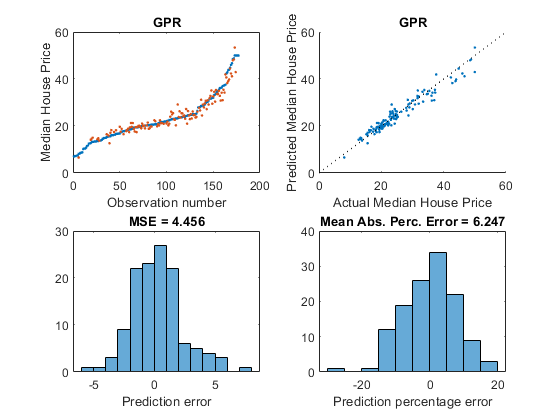

mdl = fitrgp(houseTrain,'MedianValue','Standardize',true);
qualpred = predict(mdl,houseTest);
evaluatefitHouse(houseTest.MedianValue,qualpred,'GPR')